# ESTABILIDAD

s=tf('s'); %Definimos s como una variable simbolica
G=zpk([],[-10 -5 1+i -1+i],80)

G =
 
                  80
  ----------------------------------
  (s+10) (s+5) (s+(1-1i)) (s-(1+1i))
 
Continuous-time zero/pole/gain model.



%rlocus(G)

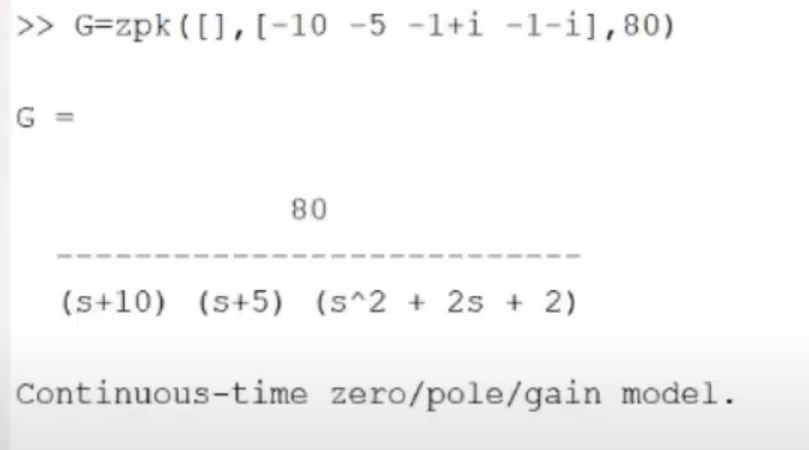

#### `BODE`

G1=zpk([-1/3],[-1/5 0],6/5)

G1 =
 
  1.2 (s+0.3333)
  --------------
    s (s+0.2)
 
Continuous-time zero/pole/gain model.



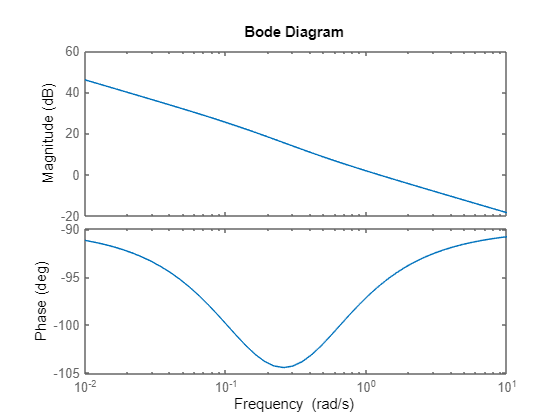

bode(G1)

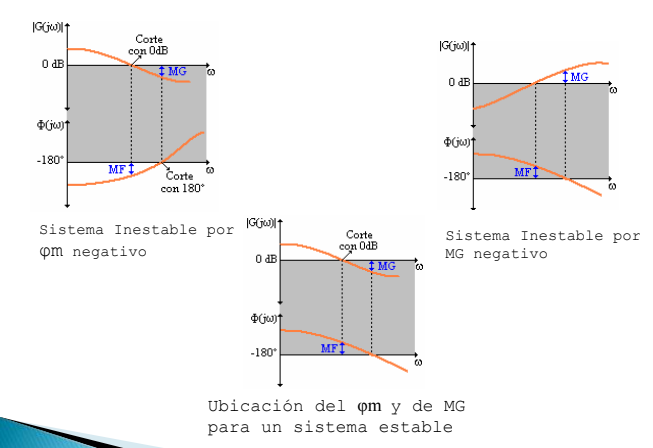

G2=zpk([],[-1 -2 0],1)

G2 =
 
        1
  -------------
  s (s+1) (s+2)
 
Continuous-time zero/pole/gain model.



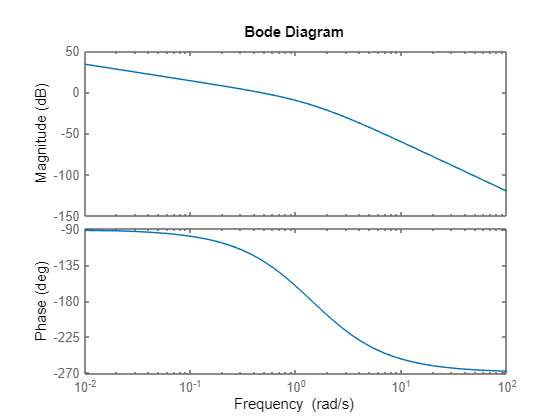

bode(G2)

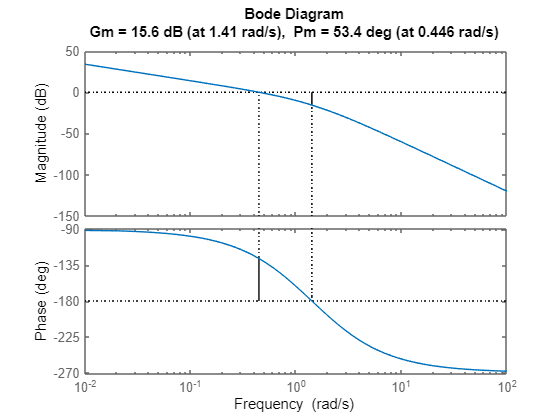

margin(G2)

#### **NYQUIST**

- **EJEMPLO DE UN SISTEMA INESTABLE**

G3=zpk([],[1 2],2) %sistema con dos polos

G3 =
 
       2
  -----------
  (s-1) (s-2)
 
Continuous-time zero/pole/gain model.



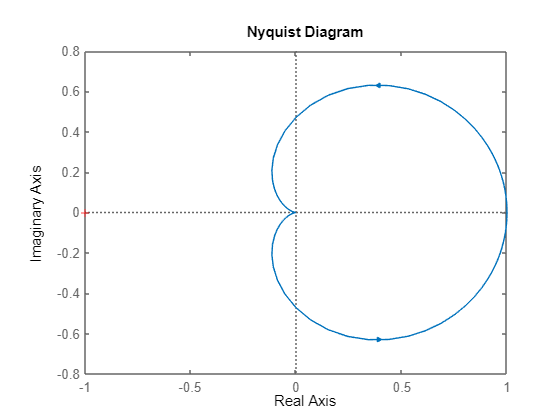

nyquist(G3)

%este sistema es inestable ya que como podemos apreciar en la grafica el
%punto pasara por (-1,0 ) en sentido antihorario


- **EJEMPLO PARA UN SISTEMA ESTABLE**

G4=zpk([],[-1 -2 ],2) %sistema con dos polos

G4 =
 
       2
  -----------
  (s+1) (s+2)
 
Continuous-time zero/pole/gain model.



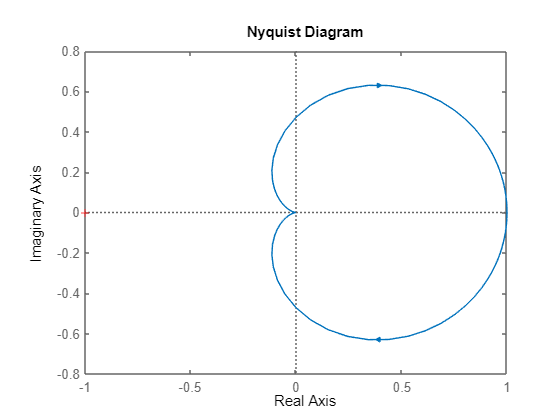

nyquist(G4)

%es sistema es ESTABLE ya que no para por el punto -1,0 y va en sentido
%horario


- **MARGEN DE GANANCIAS PARA QUE EL SISTEMA SEA ESTABLE**

G5=zpk([],[-1 -2 0],1)

G5 =
 
        1
  -------------
  s (s+1) (s+2)
 
Continuous-time zero/pole/gain model.



GM=zpk([],[-1 -2 0],6)

GM =
 
        6
  -------------
  s (s+1) (s+2)
 
Continuous-time zero/pole/gain model.



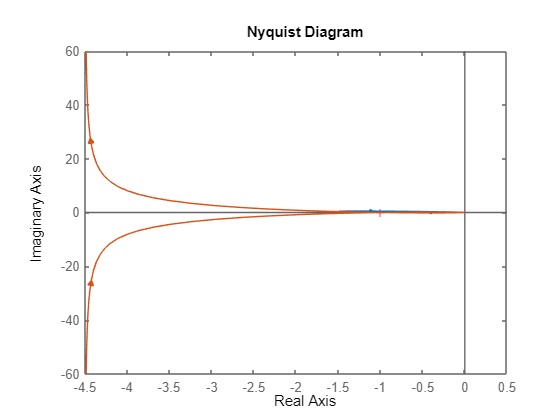

nyquist(G,GM)

#### **CRITERO LGR**

GL=zpk([],[0 -1 -2],2)

GL =
 
        2
  -------------
  s (s+1) (s+2)
 
Continuous-time zero/pole/gain model.



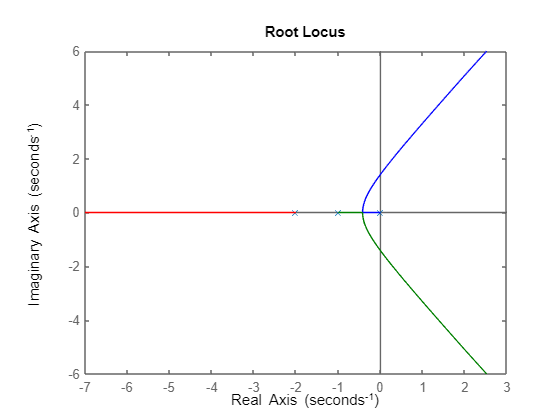

rlocus(GL)

- **EJEMPLO DE INESTABILIDAD PARA TODO VALOR DE K**

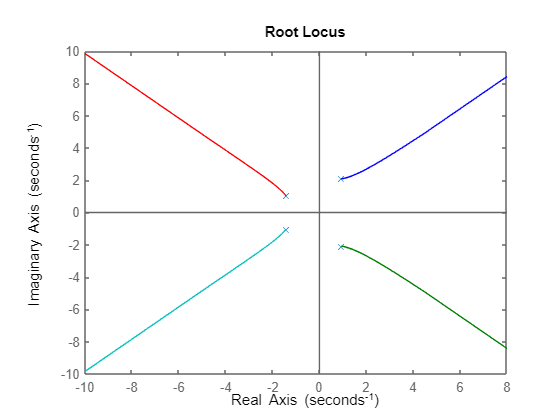

GL1=tf(10,[1 1 3 9 16]);
rlocus(GL1)

- **EJEMPLO DE ESTABILIDAD PARA VALORES K<6**

GL2 = zpk([],[-1 -2 0],1)

GL2 =
 
        1
  -------------
  s (s+1) (s+2)
 
Continuous-time zero/pole/gain model.



rlocus(GL2)